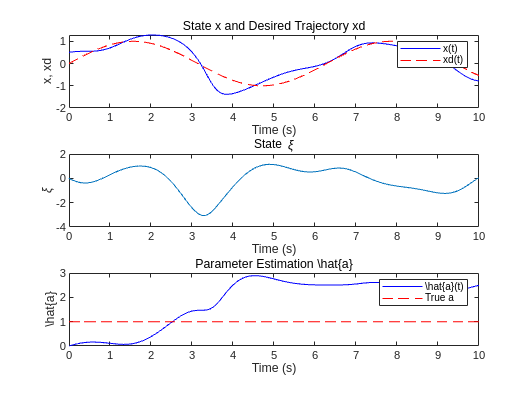

% Define parameters and initial conditions
a_true = 1;  % True value of the parameter a
x0 = 0.5;    % Initial condition for x
xi0 = 0;     % Initial condition for xi
a_hat0 = 0;  % Initial estimate of a

% Desired trajectory for x
xd = @(t) sin(t);

% Adaptive gain
gamma = 2;
k1 = 6; % Control gain

% Simulation time
tspan = [0 10];

% Solve the system of differential equations
initial_conditions = [x0; xi0; a_hat0];
[t, states] = ode45(@(t, state) system_dynamics(t, state, xd, gamma, a_true, k1), tspan, initial_conditions);

% Extract states
x = states(:, 1);
xi = states(:, 2);
a_hat = states(:, 3);

% Plot results
figure;
subplot(3, 1, 1);
plot(t, x, 'b', t, xd(t), 'r--');
title('State x and Desired Trajectory xd');
xlabel('Time (s)');
ylabel('x, xd');
legend('x(t)', 'xd(t)');

subplot(3, 1, 2);
plot(t, xi);
title('State \xi');
xlabel('Time (s)');
ylabel('\xi');

subplot(3, 1, 3);
plot(t, a_hat, 'b', t, a_true*ones(size(t)), 'r--');
title('Parameter Estimation \hat{a}');
xlabel('Time (s)');
ylabel('\hat{a}');
legend('\hat{a}(t)', 'True a');


% Differential equations for the system

function dxdt = system_dynamics(t, state, xd, gamma, a_true, k1)
    x = state(1);
    xi = state(2);
    a_hat = state(3);
    
    % Desired trajectory and its derivative
    xd_t = xd(t);
    dxd_t = cos(t);
    
    % Backstepping control law
    z = x - xd_t;
    u = -k1 * z - a_hat * x + x^3 + dxd_t;
    
    % Adaptive law
    da_hat = gamma * z * x;
    
    % System dynamics
    dx = a_true * x - x^3 + xi;
    dxi = u;
    
    dxdt = [dx; dxi; da_hat];
end